# Problema 1

function [p_val, p_expr] = lagrangeInterpolation(x_nodes, y_nodes, x_eval)
% INPUT:
%   x_nodes  - vectorul nodurilor de interpolare 
%   y_nodes  - vectorul valorilor functiei in noduri 
%   x_eval   - vectorul punctelor in care se evalueaza polinomul
%
% OUTPUT:
%   p_val    - valorile numerice ale polinomului in punctele x_eval
%   p_expr   - expresia simbolica a polinomului
 
    % Numarul de noduri
    n = length(x_nodes);

    % Asiguram ca x_eval este coloana
    x_eval = x_eval(:);

    % Initializam vectorul rezultat
    p_val = zeros(size(x_eval));

    % Initializare variabila simbolica si polinom simbolic
    syms x;
    p_expr = 0;

    % Construim expresia simbolica si evaluam numeric
    for i = 1:n
        % Initializare L_i(x)
        L_i = 1;
        for j = 1:n
            if j ~= i
                L_i = L_i * (x - x_nodes(j)) / (x_nodes(i) - x_nodes(j));
            end
        end
        % Adunam termenul y_i * L_i(x)
        p_expr = p_expr + y_nodes(i) * L_i;
    end

    % Evaluam numeric in punctele dorite
    for k = 1:length(x_eval)
        p_val(k) = double(subs(p_expr, x, x_eval(k)));
    end

    % Simplificam 
    p_expr = expand(p_expr);  % dezvoltare
end

% Definim functia reala
f = @(x) 2*x.^3 - 3*x.^2 + x + 1;

% Alegem nodurile de interpolare
x_nodes = linspace(-2, 2, 5)  % 5 noduri => grad max 4 pentru interpolare

x_nodes =     -2    -1     0     1     2


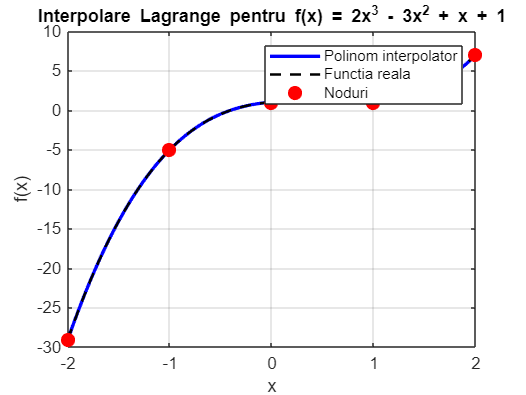


% Calculam valorile functiei in noduri
y_nodes = f(x_nodes);

% Puncte in care evaluam polinomul
x_eval = linspace(min(x_nodes), max(x_nodes), 300);

% Calculam valorile polinomului de interpolare
[p_val, p_expr] = lagrangeInterpolation(x_nodes, y_nodes, x_eval);

% Afisam graficul
figure;
plot(x_eval, p_val, 'b-', 'LineWidth', 2); hold on;
fplot(f, [min(x_nodes), max(x_nodes)], 'k--', 'LineWidth', 1.5); % functia reala
plot(x_nodes, y_nodes, 'ro', 'MarkerSize', 8, 'MarkerFaceColor', 'r');
grid on;
title('Interpolare Lagrange pentru f(x) = 2x^3 - 3x^2 + x + 1');
xlabel('x'); ylabel('f(x)');
legend('Polinom interpolator', 'Functia reala', 'Noduri');


% Afisam si polinomul simbolic in consola
disp('Polinomul Lagrange gasit:');

Polinomul Lagrange gasit:


pretty(p_expr);

   3      2
2 x  - 3 x  + x + 1

